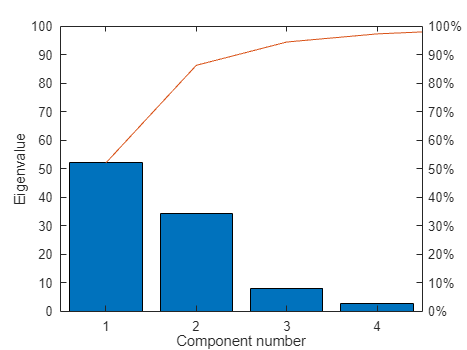

%因子分析
%基于8项经济指标的中国31省市自治区的因子分析（主因解）
regions2004                                              %将保存的数据导入内存
X=zscore(data);                                          %原始数据集体标准化
% [E,score,eigv,T]=princomp(X);                            %调用主成分分析程序
[E,score,eigv,T]=pca(X);                            %调用主成分分析程序
per=100*eigv/sum(eigv);                                  %计算方差贡献百分比
Cum=cumsum(per);                                         %计算方差贡献累计百分比
figure(1);                                               %创建第一个图形窗口
pareto(per);                                             %将贡献率绘制成直方图
xlabel('Component number');                              %横轴标签(成分数)
ylabel('Eigenvalue');                                    %纵轴标签(特征值)

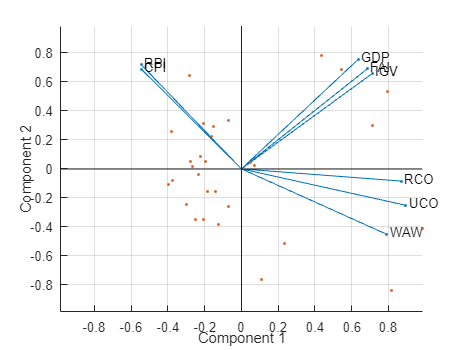

lambda=diag(eigv);                                       %用特征值构成对角阵
C=sqrtm(lambda);                                         %将对角矩阵对角线元素化为平方根
A=E*C;                                                   %计算载荷矩阵(转换为负值)
Co1=A(:,1).^2;                                           %提取1个主成分的公因子方差
Co2=Co1+A(:,2).^2;                                       %提取2个主成分的公因子方差
Comm=[Co1,Co2];                                          %将4个公因子方差向量合并为一个矩阵
F=zscore(score);                                         %主成分得分集体标准化并转换为负值
figure(2);                                               %创建第二个图形窗口
biplot(A(:,1:2),'scores',F(:,1:2),'varlabels', varname); %绘制载荷-得分二重散点图

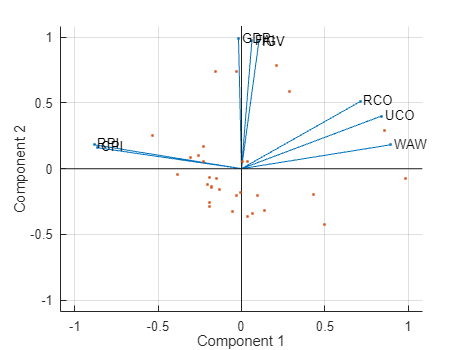


%主因解的正交旋转
[B, T]= rotatefactors(A(:,1:2), 'Method','varimax');     %主因解的第一、第二载荷旋转
S=F(:,1:2)*T;                                            %计算旋转的后第一、第二因子得分
figure(3);   
biplot(B(:,1:2),'scores',S(:,1:2),'varlabels', varname); %绘制旋转后载荷-得分二重散点图